clf;
homedir='\Users\editabulovaite\Documents\PhD_Year2\region_puncta_distribution\Edita_punctanew\';

dirNameForFileName=strrep(homedir,'/','-slash-'); %if the dirName is in fact a path containing several directories, we substitute any / to the string -slash- as / is not a valid file name character
dirNameForFileName=strrep(dirNameForFileName,'\','-slash-');

delimiter='\t';
startRow = 2;



turnover_dir=dir('Density_Intensity_halflife_CIs_08072020.csv');
turnover_dir = readtable(turnover_dir.name);


MEAN_Halo =turnover_dir(1:110,13);
MEAN_Halo=table2array(MEAN_Halo);
SD_Halo_neg =turnover_dir(1:110,14);
SD_Halo_neg=table2array(SD_Halo_neg);
SD_Halo_pos =turnover_dir(1:110,14);
SD_Halo_pos=table2array(SD_Halo_pos);

MEAN_eGFP =turnover_dir(1:110,5);
MEAN_eGFP=table2array(MEAN_eGFP);
SD_eGFP_neg =turnover_dir(1:110,6);
SD_eGFP_neg=table2array(SD_eGFP_neg);
SD_eGFP_pos =turnover_dir(1:110,7);
SD_eGFP_pos=table2array(SD_eGFP_pos);

Regions =turnover_dir(1:110,8);
Regions = table2array(Regions);
Regions = categorical(Regions);


SD_Halo_neg=convertCharsToStrings(SD_Halo_neg);
SD_Halo_pos=convertCharsToStrings(SD_Halo_pos);
SD_eGFP_neg=convertCharsToStrings(SD_eGFP_neg);
SD_eGFP_pos=convertCharsToStrings(SD_eGFP_pos);


c=[0.85 0.33 0.1; 0.64 0.08 0.18; 0.47 0.67 0.19; 0.93 0.69 0.13; 0 0.45 0.74; 0.79 0.55 0.94; 0.65 0.84 0.52; 0.3 0.75 0.93; 0.65 0.65 0.65; 0.86 0.45 0.71; 0.49 0.18 0.56; 0.24 0.78 0.78];
gscatter(MEAN_eGFP,MEAN_Halo,Regions,c,'.',20);
hold on
legend("Location","bestoutside")
xlabel('PSD95 half-life (density-based)')
ylabel('PSD95 half-life (intensity-based)')
hold on
r=corr(MEAN_eGFP,MEAN_Halo)

r = 0.9088

[R,P] = corr(MEAN_eGFP,MEAN_Halo)

R = 0.9088

P = 8.3732e-43

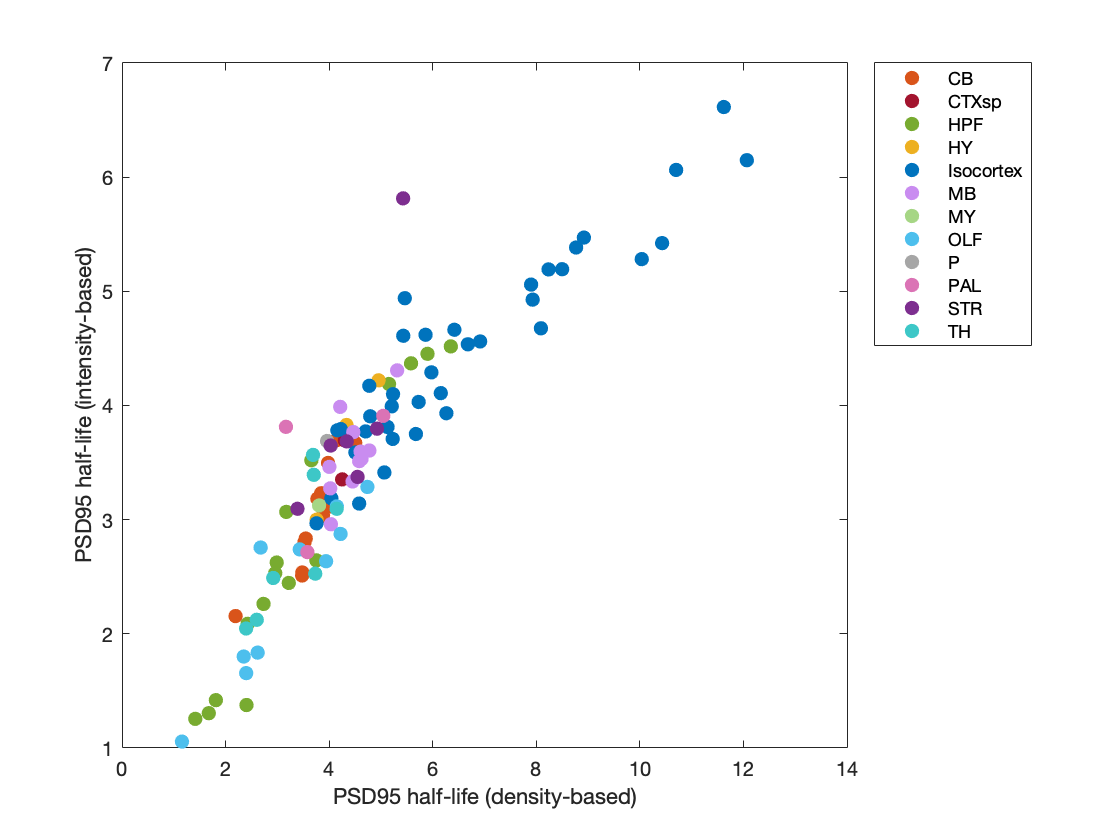


hold off
saveas(gcf,'correlation_intensity_density_halflife','png')
saveas(gcf,'correlation_intensity_density_halflife','pdf')